# **Smartfin: Mathworks Symposium**

# imufilter: Estimate Orientation from IMU data

We are using MATLAB's [imufilter package](https://www.mathworks.com/help/nav/ref/imufilter-system-object.html) that uses an in-built Kalman Filter to estimate pose using IMU values for a 3D object.

We load the IMU data which contains recorded accelerometer, gyroscope sensor data from the vectornav, a device oscillating in pitch (around *y*-axis), then yaw (around *z*-axis), and then roll (around *x*-axis). The sampling rate of this is 400 Hz.

We ing to be comparing the actual data (roll/pitch/yaw orientation values from the VectorNav) versus the estimated data (roll/pitch/yaw orientation estimates using IMU values from Vector Nav). 

`The imufilter` filter correctly estimates the change in orientation from an assumed north-facing initial orientation. However, the device's x and y-axis were pointing the opposite orientation, therefore the values are negated here in order to adjust for that.

filename_acc = 'cleaned_data/acc_values_vector_nav_45.csv';
filename_gyr = 'cleaned_data/gyr_values_vector_nav_45.csv';
filename_ypr = 'cleaned_data/ypr_values_vector_nav_45.csv';
filename_quat = 'cleaned_data/quat_values_vector_nav_45.csv';

Fs = 400;

acc = csvread(filename_acc,1, 1);
gyr = csvread(filename_gyr,1, 1);
ypr = csvread(filename_ypr,1, 1);

quat = csvread(filename_quat,1, 1);


accelerometerReadings = acc(1:7218,:) ; 
%disp(accelerometerReadings);
gyroscopeReadings = gyr(1:7218, :);
%disp(gyroscopeReadings);

#### The test case we are testing here is a 45 degree rotation about the pitch or y-axis. We will plot the actual orientation values below:

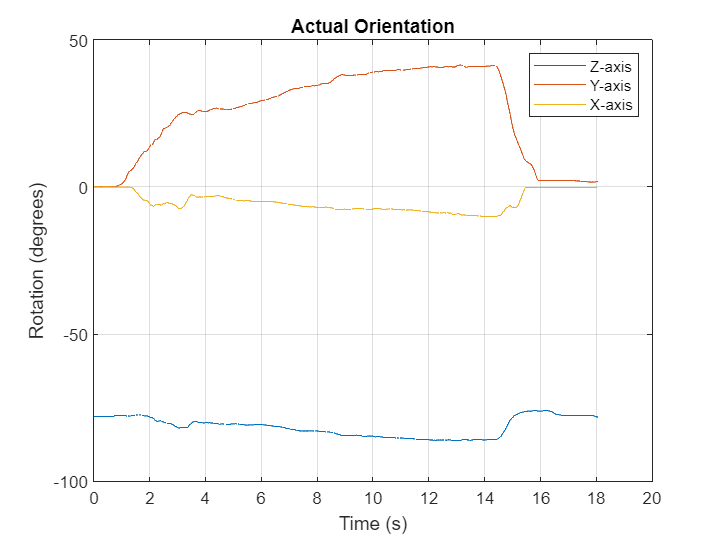

time = [1:size(ypr)]/Fs';
plot(time,ypr(:, 1))
grid on;
hold on;
plot(time,ypr(:, 2))
plot(time,ypr(:, 3))
title('Actual Orientation')
hold off;
legend('Z-axis', 'Y-axis', 'X-axis')
xlabel('Time (s)')
ylabel('Rotation (degrees)')

Now we create an `imufilter` System object™ and set our sampling rate to 400Hz as mentioned above. Then, we specify a decimation factor of two, this is to reduce the computation time of the algorithm while still going through the entire dataset.

dec = 2;
filter = imufilter('SampleRate',Fs,'DecimationFactor', dec, 'ReferenceFrame','ENU');

Then we pass the accelerometer readings and gyroscope readings to this newly created `imufilter` object, `filter. This will output pose_q, which is the `an estimate of the sensor body orientation over time. This output is a vector of quaternions (in order to avoid gimbal lock).

pose_q = filter(accelerometerReadings,gyroscopeReadings);

Here we are converting the quaternion pose estimation into euler angles for easier visualization. This is then being stored in a matrix and written to a csv file.

m = (eulerd(pose_q, ['ZYX'], 'frame'));
writematrix(m,'Orientation_vector_nav_results.csv') 

Now, we are going to focus on our axis of interest, the **pitch (y-axis).**

We are plotting the orientation in Euler Angles in degrees over time. This refers to the angular displacement of our Smartfin from it's starting position to its final position. 

We are plotting time from 0 to ~20 seconds, and we are taking measurements separated by the decimation value of 2 defined above. 

`imufilter` fusion correctly estimates the change in orientation from an assumed north-facing initial orientation. However, the device's *x*-axis was pointing southward when recorded. To correctly estimate the orientation relative to the true initial orientation or relative to NED, use `ahrsfilter`.

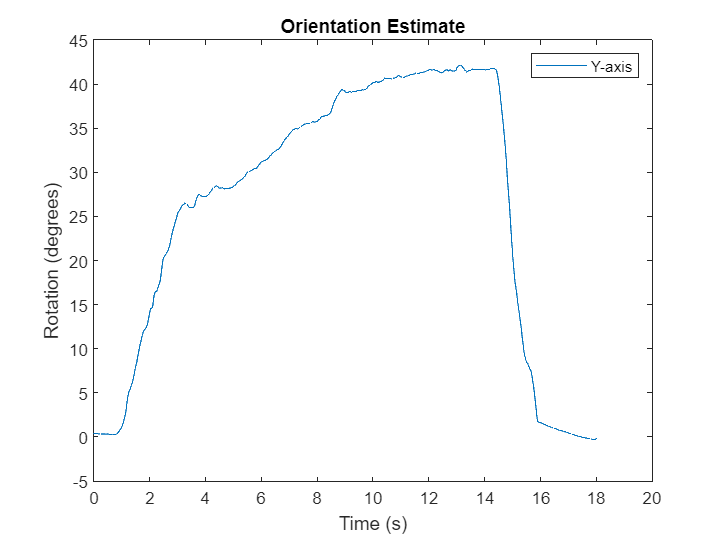

time = (0:dec:size(accelerometerReadings,1)-1)/Fs;

plot(time, m(:, 2))
title('Orientation Estimate')
legend('Y-axis')
xlabel('Time (s)')
ylabel('Rotation (degrees)')

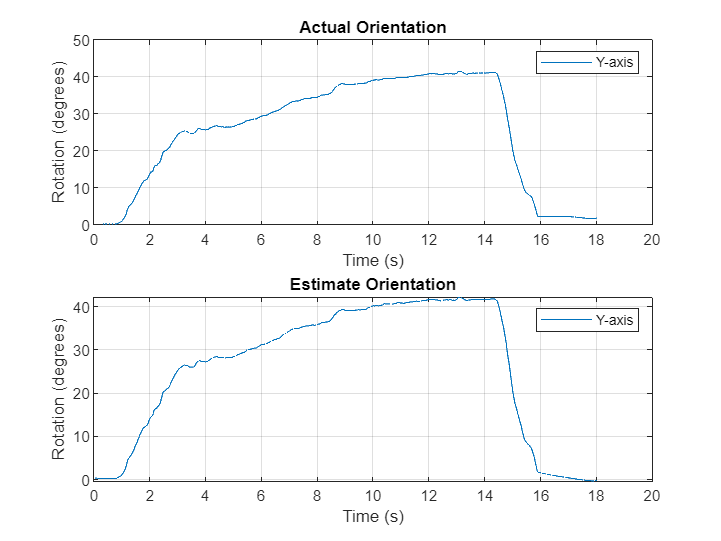

figure(1)
subplot(2, 1, 1);
time = [1:size(ypr)]/Fs';
plot(time,ypr(:, 2))
grid on;
title('Actual Orientation')
hold off;
legend('Y-axis')
xlabel('Time (s)')
ylabel('Rotation (degrees)')


subplot(2,1,2) ;
time = (0:dec:size(accelerometerReadings,1)-1)/Fs;
plot(time,m(:, 2))
grid on;
title('Estimate Orientation')
hold off;
legend('Y-axis')
xlabel('Time (s)')
ylabel('Rotation (degrees)')

## Results:

From the imufilter we used above, we can see that it is pretty good at estimating pose values just using acceleration and gyroscope IMU values. Our next steps would be trying this experiment out in various other axes and incorporating different types of motion (i.e. moving two axes at the same time, moving > 180 degrees, etc.)

# [Filtering of IMU data using Kalman filter](https://scholars.csus.edu/esploro/outputs/graduate/Filtering-of-IMU-data-using-Kalman/99257831038101671) - CSU Sacramento

**Background: **This was code that we adapted mostly from the *Filtering of IMU Data Using Kalman Filter* paper from CSU Sacramento authored by *Naveen Prabu Palanisamy. *This paper esentially uses a kalman filter to reduce noise in their IMU data and effectively predict the position/pose of an object. We tried recreating this using a pendulum motion. The results weren't exactly to our favor since our values were very skewed and our velocity and position values were out of proportion and can't really be be used to our favor. We wanted to include this as progress because it helped us learn more about the Kalman Filtering Process.

Our test case consisted of recreating a pendulum motion with a sampling rate of 100Hz. You can see the graphs and outputs below. The u1 variables are initialized to hold the acceleration values, the u2 variables are initialized to hold the velocity values, and the u3 variables are initialized to hold the position values.

clc;
clear all; %%File reading
filename = 'cleaned_data/1m_positive_fast_time.csv';
num = csvread(filename,1);
%disp(num)
time=[];  u=[];   k=[];
u1x=[];  u2x=[];  u3x=[];
u1y=[];  u2y=[];  u3y=[];
u1z=[];  u2z=[];  u3z=[];


### X - Direction

The u1, u2, and u3 variables are split up into the x, y, and z directions. The u2 and u3 variables are used to store the velocity and position values and are not inserted into the kalman filter

n = 972;
%disp(num(2, 2))
for i = 1:1:n
    time(i) = num(i, 2);
    %disp("time: " + num(i))
    u1x(i) = 9.8 * num(i, 3);        % x direction only
    %disp("u1: " + num(i+n))
    u2x(i) = 9.8 * num(i, 4);
    %disp("u2: " + num(i+(2*n)))
    u3x(i) = 9.8 * num(i, 5);
    %disp("u3: " + num(i+(3*n)))
end
time = time';  u1x = u1x';  u2x = u2x';  u3x = u3x';


### Y - Direction

n = 972;
%disp(num(2, 2))
for i = 1:1:n
    time(i) = num(i, 2);
    %disp("time: " + num(i))
    u1y(i) = 9.8 * num(i, 4);        % y direction only
    %disp("u1: " + num(i+n))
    u2y(i) = 9.8 * num(i, 5);
    %disp("u2: " + num(i+(2*n)))
    u3y(i) = 9.8 * num(i, 3);
    %disp("u3: " + num(i+(3*n)))
end
time = time';  u1y = u1y';  u2y = u2y';  u3y = u3y';


### Z - Direction

n = 972;
%disp(num(2, 2))
for i = 1:1:n
    time(i) = num(i, 2);
    %disp("time: " + num(i))
    u1z(i) = 9.8 * num(i, 5);        % z direction only
    %disp("u1: " + num(i+n))
    u2z(i) = 9.8 * num(i, 3);
    %disp("u2: " + num(i+(2*n)))
    u3z(i) = 9.8 * num(i, 4);
    %disp("u3: " + num(i+(3*n)))
end
time = time';  u1z = u1z';  u2z = u2z';  u3z = u3z';

## define our meta - variables

Here A is set as the transition matrix using the dt value labeled above. H is defined as the measurement matrix and is set as the identity matrix to begin with

duration = size(time); %how long the simulation is
dt = 0.039;          %10 Hz continuously looking for measurement %0.039

## define update equations

A = [1 dt dt^2/2;0 1 dt;0   0 1];   %transition matrix
B = 0;
H = [1 0 0;0 1 0;0 0 1];     %genral form matrices ; measurement matrix

## define main variables

ux=0; uy = 0; uz = 0;
k1x = [u1x u2x u3x];              %control vector ; acceleration matrix
k1y = [u1y u2y u3y];              %control vector ; acceleration matrix
k1z = [u1z u2z u3z];              %control vector ; acceleration matrix
Q= [0; 0; 0];                  %initized state ; [position velocity]
Q_estimate_x = Q;
Q_estimate_y = Q;
Q_estimate_z = Q;
P = eye(3);         % q --> estimated process error covariance.
Ex = eye(3);                  %estimate of initial object position
R = [1 0 0 ;0 1 0;0 0 1];

## Initialize result variables

Z_p_x = [];    Z_v_x = [];    Z_a_x = [];
Z_p_y = [];    Z_v_y = [];    Z_a_y = [];
Z_p_z = [];    Z_v_z = [];    Z_a_z = [];


### Variables for X Direction

x_estimate_az_x = [];  y_estimate_az_x = [];  z_estimate_az_x =[];  %estimate of the object path using Kalman filter
u3_bias_x=[];   u3_perfect_x =[];
ll_x = mean(u3x);
%taking the mean of u3 will give the value and it is subtracted from
%each u3 to find bias and u3_perfect is calculated.

for t = 1:1:duration
    u3_bias_x(t) = u3x(t)-ll_x;
    u3_perfect_x(t) = u3x(t)-u3_bias_x(t);
end

### Variables for Y Direction

x_estimate_az_y = [];  y_estimate_az_y = [];  z_estimate_az_y =[];  %estimate of the object path using Kalman filter
u3_bias_y=[];   u3_perfect_y =[];
ll_y = mean(u3y);
%taking the mean of u3 will give the value and it is subtracted from
%each u3 to find bias and u3_perfect is calculated.

for t = 1:1:duration
    u3_bias_y(t) = u3y(t)-ll_y;
    u3_perfect_y(t) = u3y(t)-u3_bias_y(t);
end

### Variables for Z Direction

x_estimate_az_z = [];  y_estimate_az_z = [];  z_estimate_az_z =[];  %estimate of the object path using Kalman filter
u3_bias_z=[];   u3_perfect_z =[];
ll_z = mean(u3z);
%taking the mean of u3 will give the value and it is subtracted from
%each u3 to find bias and u3_perfect is calculated.

for t = 1:1:duration
    u3_bias_z(t) = u3z(t)-ll_z;
    u3_perfect_z(t) = u3z(t)-u3_bias_z(t);
end

## Kalman Filter for X

Q_estimate_x= [0; 0; 0];
for t = 1:1:duration
    % Predict
    % Predicted State
    Q_estimate_curr = A * Q_estimate_x + B * ux;    %-----------1
    Z_p_x = [Z_p_x; Q_estimate_curr(1)];
    Z_v_x = [Z_v_x; Q_estimate_curr(2)];
    Z_a_x = [Z_a_x; Q_estimate_curr(3)];
    %predicted next covariance
    P = A * P * A' + Ex;                         %-----------2
    % Update
    %Kalman Gain
    K = P*H'*inv(H*P*H'+R);                          %-----------3
    
    % Update the state estimate.
    y = [Q_estimate_curr(1);Q_estimate_curr(2);u3x(t)];
    Q_estimate_x = Q_estimate_curr + K * (y - H * Q_estimate_curr); %--4
    
    % update covariance estimation.
    P =  (eye(3)-K*H)*P;         %-----------5
    % Store for Plotting
    x_estimate_az_x = [x_estimate_az_x; Q_estimate_x(1)];
    y_estimate_az_x = [y_estimate_az_x; Q_estimate_x(2)];
    z_estimate_az_x = [z_estimate_az_x; Q_estimate_x(3)];
end

## Kalman Filter for Y

Q_estimate_y= [0; 0; 0];
for t = 1:1:duration
    % Predict
    % Predicted State
    Q_estimate_curr = A * Q_estimate_y + B * uy;    %-----------1
    Z_p_y = [Z_p_y; Q_estimate_curr(1)];
    Z_v_y = [Z_v_y; Q_estimate_curr(2)];
    Z_a_y = [Z_a_y; Q_estimate_curr(3)];
    %predicted next covariance
    P = A * P * A' + Ex;                         %-----------2
    % Update
    %Kalman Gain
    K = P*H'*inv(H*P*H'+R);                          %-----------3
    
    % Update the state estimate.
    y = [Q_estimate_curr(1);Q_estimate_curr(2);u3y(t)];
    Q_estimate_y = Q_estimate_curr + K * (y - H * Q_estimate_curr); %--4
    
    % update covariance estimation.
    P =  (eye(3)-K*H)*P;         %-----------5
    % Store for Plotting
    x_estimate_az_y = [x_estimate_az_y; Q_estimate_y(1)];
    y_estimate_az_y = [y_estimate_az_y; Q_estimate_y(2)];
    z_estimate_az_y = [z_estimate_az_y; Q_estimate_y(3)];
end

## Kalman Filter for Z

Q_estimate_z= [0; 0; 0];
for t = 1:1:duration
    % Predict
    % Predicted State
    Q_estimate_curr = A * Q_estimate_z + B * uz;    %-----------1
    Z_p_z = [Z_p_z; Q_estimate_curr(1)];
    Z_v_z = [Z_v_z; Q_estimate_curr(2)];
    Z_a_z = [Z_a_z; Q_estimate_curr(3)];
    %predicted next covariance
    P = A * P * A' + Ex;                         %-----------2
    % Update
    %Kalman Gain
    K = P*H'*inv(H*P*H'+R);                          %-----------3
    
    % Update the state estimate.
    y = [Q_estimate_curr(1);Q_estimate_curr(2);u3z(t)];
    Q_estimate_z = Q_estimate_curr + K * (y - H * Q_estimate_curr); %--4
    
    % update covariance estimation.
    P =  (eye(3)-K*H)*P;         %-----------5
    % Store for Plotting
    x_estimate_az_z = [x_estimate_az_z; Q_estimate_z(1)];
    y_estimate_az_z = [y_estimate_az_z; Q_estimate_z(2)];
    z_estimate_az_z = [z_estimate_az_z; Q_estimate_z(3)];
end

## Plotting for X

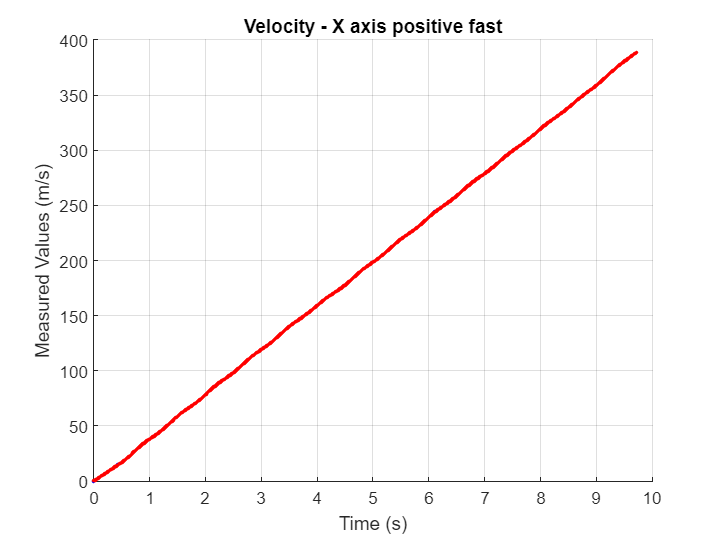

tt = 1:1:size(Z_v_x);
%x
figure;
hold on
grid on
plot(time(tt),Z_v_x,'-b.');
plot(time(tt),y_estimate_az_x,'-r.');
title('Velocity - X axis positive fast');
xlabel('Time (s)');
ylabel ('Measured Values (m/s)');
hold off

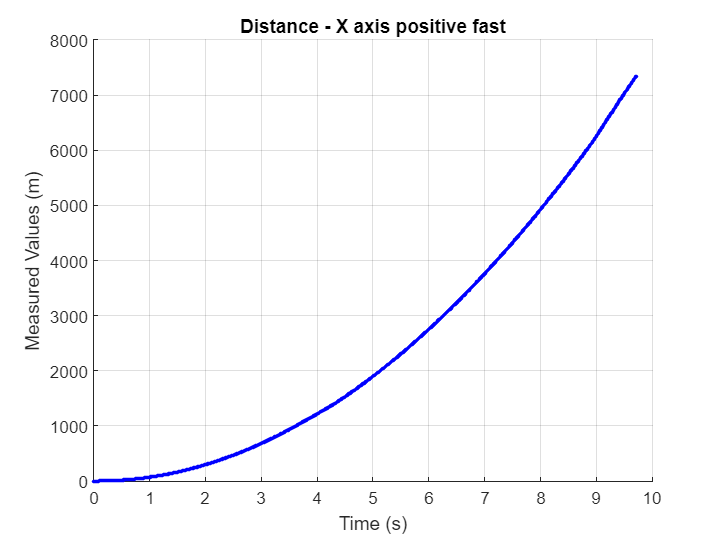


figure;
hold on
grid on
plot(time(tt),Z_p_x,'-r.');
plot(time(tt),x_estimate_az_x,'-b.');
title('Distance - X axis positive fast');
xlabel('Time (s)');
ylabel ('Measured Values (m)');
hold off

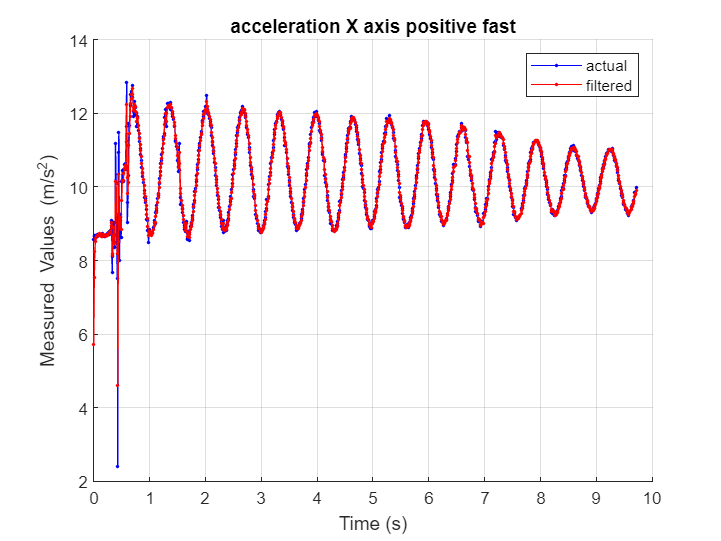


figure;
hold on
grid on
plot(time(tt),u3x(tt),'-b.');
plot(time(tt),z_estimate_az_x,'-r.');
title('acceleration X axis positive fast');
legend('actual', 'filtered')
xlabel('Time (s)');
ylabel ('Measured Values (m/s^-^2)');
hold off

## Plotting for Y

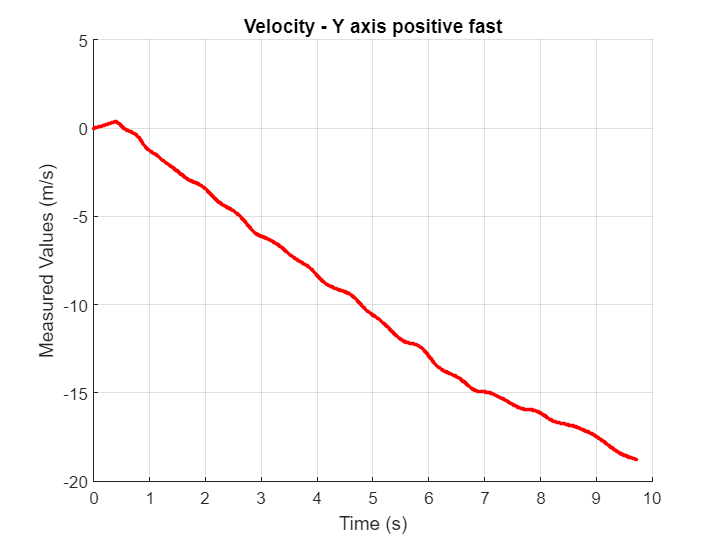

tt = 1:1:size(Z_v_y);
%x
figure;
hold on
grid on
plot(time(tt),Z_v_y,'-b.');
plot(time(tt),y_estimate_az_y,'-r.');
title('Velocity - Y axis positive fast');
xlabel('Time (s)');
ylabel ('Measured Values (m/s)');
hold off

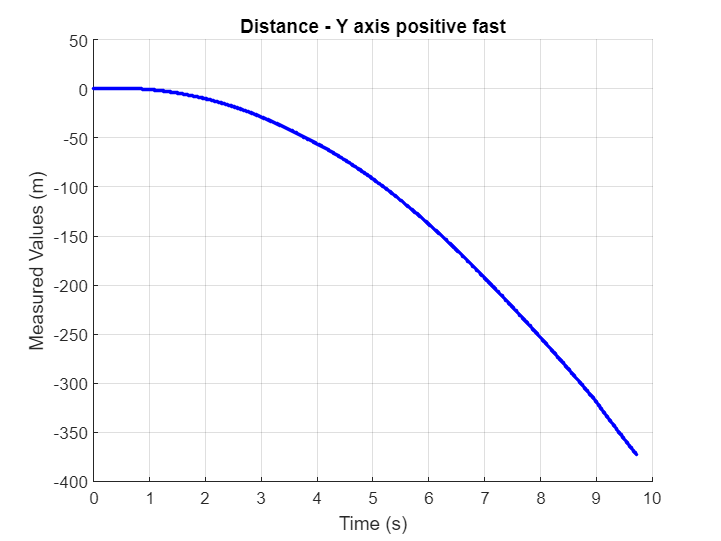


figure;
hold on
grid on
plot(time(tt),Z_p_y,'-r.');
plot(time(tt),x_estimate_az_y,'-b.');
title('Distance - Y axis positive fast');
xlabel('Time (s)');
ylabel ('Measured Values (m)');
hold off

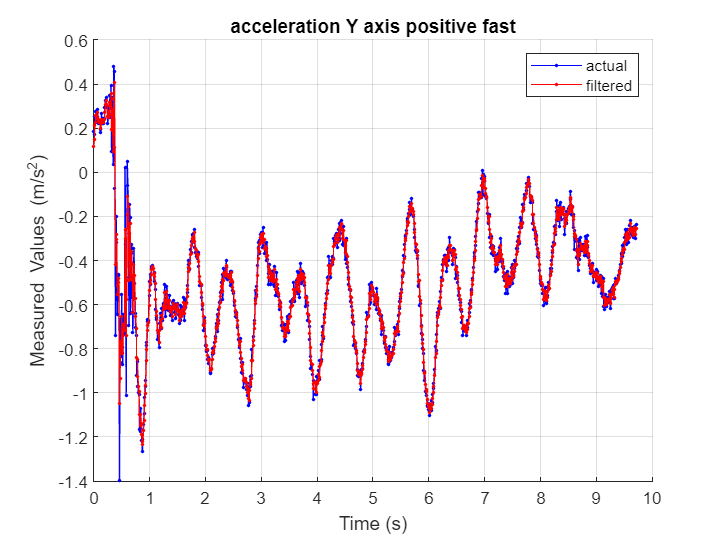


figure;
hold on
grid on
plot(time(tt),u3y(tt),'-b.');
plot(time(tt),z_estimate_az_y,'-r.');
title('acceleration Y axis positive fast');
legend('actual', 'filtered')
xlabel('Time (s)');
ylabel ('Measured Values (m/s^-^2)');
hold off

## Plotting for Z

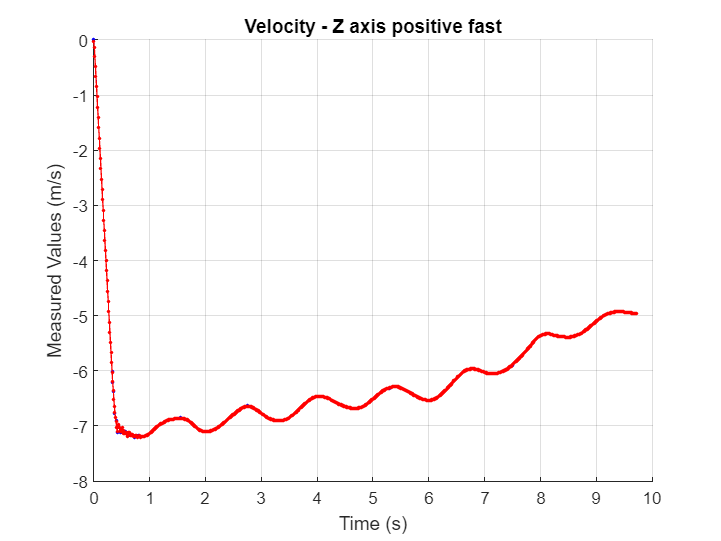

tt = 1:1:size(Z_v_z);
%x
figure;
hold on
grid on
plot(time(tt),Z_v_z,'-b.');
plot(time(tt),y_estimate_az_z,'-r.');
title('Velocity - Z axis positive fast');
xlabel('Time (s)');
ylabel ('Measured Values (m/s)');
hold off

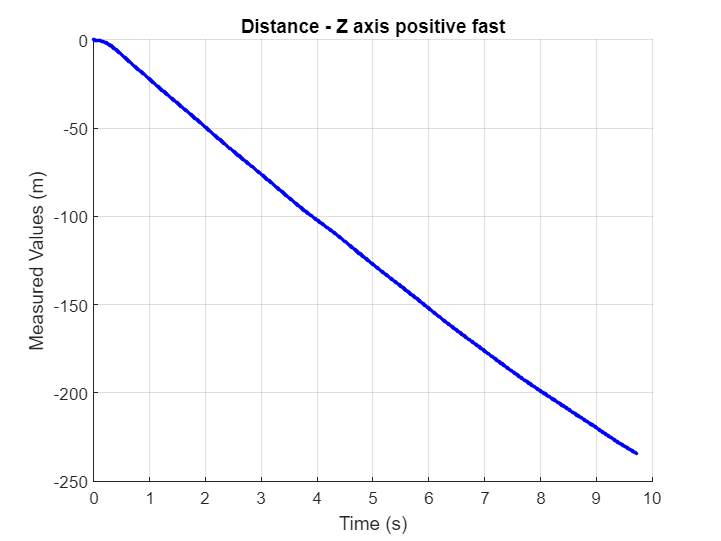


figure;
hold on
grid on
plot(time(tt),Z_p_z,'-r.');
plot(time(tt),x_estimate_az_z,'-b.');
title('Distance - Z axis positive fast');
xlabel('Time (s)');
ylabel ('Measured Values (m)');
hold off

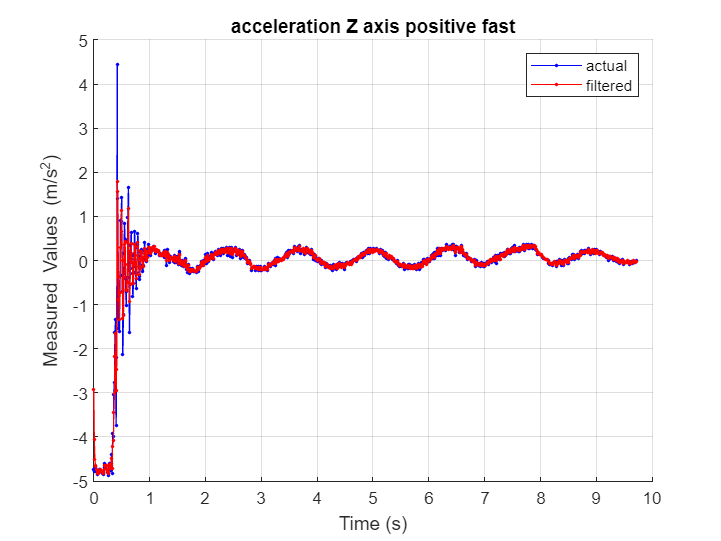


figure;
hold on
grid on
plot(time(tt),u3z(tt),'-b.');
plot(time(tt),z_estimate_az_z,'-r.');
title('acceleration Z axis positive fast');
legend('actual', 'filtered')
xlabel('Time (s)');
ylabel ('Measured Values (m/s^-^2)');
hold off

# makehgtform function: Vector Orientation for Roll, Pitch, Yaw

We are using Matlab's [makehgtform function](https://www.mathworks.com/help/matlab/ref/makehgtform.html) to visualize a vector arrow of the orientation from roll, pitch, and yaw data. This is done by utilizing the makehgtform function to rotate the vector arrow in radians based on the roll, pitch, and yaw data recorded by the IMU sensor. The orientation of the vector arrow is then animated using the [drawnow](https://www.mathworks.com/help/matlab/ref/drawnow.html) function so that the orientation of the vector arrow can be displayed over time.

pt = [0 0 0]; %starting coordinates
dir = [1 0 0 1]; %starting direction
h = quiver3(pt(1),pt(2),pt(3), dir(1),dir(2),dir(3));
xlim([-1 1])
ylim([-1 1])
zlim([-1 1])

data = csvread('FA_16_40_00_00_07_06_00 (1).csv', 1, 0);
roll = data(1:100:end, 3);
pitch = data(1:100:end, 2);
yaw = data(1:100:end, 1);

if length(roll) ~= length(pitch) || length(pitch) ~= length(yaw)
    error('Arrays are not the same length');
end

for i = 1:length(roll)
    xfm = makehgtform('xrotate', roll(i)*(pi/180), 'yrotate', ...
        pitch(i)*(pi/180), 'zrotate', yaw(i)*(pi/180)); 
        % create transformation matrix
    
    newdir = xfm * dir'; % transform the arrow direction
    
    h.UData = newdir(1);
    h.VData = newdir(2);
    h.WData = newdir(3);

    xlabel('X');
    ylabel('Y');
    zlabel('Z');
    
    drawnow % update the plot
    pause(0.05) % add a 0.05 second pause
end

**The test case we are using here is a 90 degree turn along the z-axis. Screenshots of the animation are shown below:**

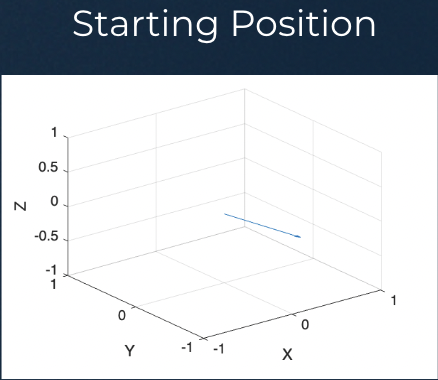                    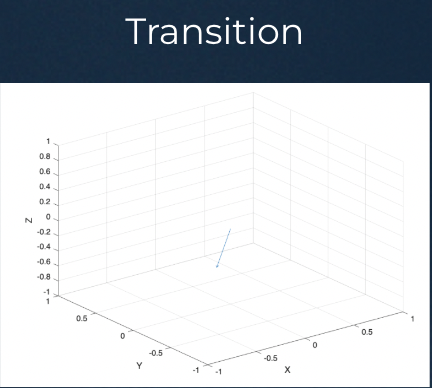                     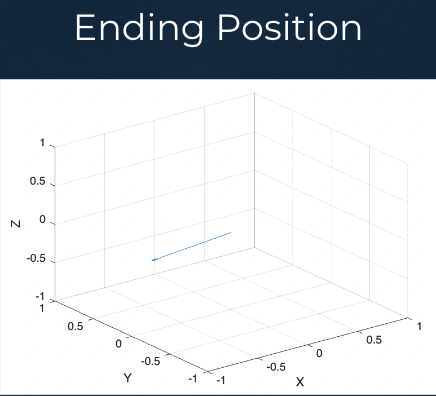

**The test case we are using here is a 45 degree** **tilt about the pitch or y-axis. Screenshots of the animation are shown below:**